# A quick walkthrough for siibralab -  Matlab interface to the siibra toolsuite 

**Siibra aims to facilitate the programmatic and reproducible incorporation of brain region features from different sources into reproducible neuroscience workflows. siibraLab is a Matlab® toolbox for accessing functions provided in siibra.**

This notebook provides a brief waltkhrough the already available functionality, focusing on access the Julich-Brain probabilistic cytoarchitectonic atlas. 

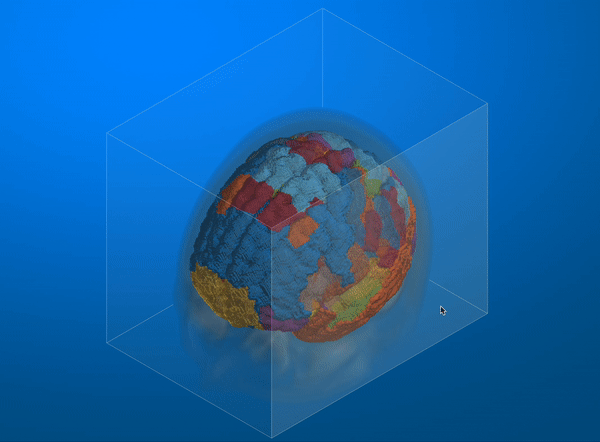


clear all;  % uncomment rows to clear the workspace and close open figures
close all;

## Accessing basic concepts: atlases, parcellations, and regions

### Predefined atlases

siibralab provides access to atlases of different species. Note that on first call of a siibralab function, the package will retrieve preconfiguration data which might take a while. The data is then cached on your local disk for future calls.

siibra.atlasOverview()

ans = 4×3 table
                                           Atlas                            Number of Parcellations    Number of Spaces
                   _____________________________________________________    _______________________    ________________

    Human          "Multilevel Human Atlas"                                           18                      4        
    Monkey         "Monkey Atlas"                                                      1                      1        
    Allen Mouse    "Allen Mouse Common Coordinate Framework v3"                        2                      1        
    Waxholm Rat    "Waxholm Space atlas of the Sprague Dawley rat brain"               4                      1        


As of now, siibra supports features of the human atlas, so let's access it.

atlas = siibra.getAtlas('human')

    "Resolved query 'human' to: Multilevel Human Atlas"



atlas =   Atlas with properties:

               Id: "juelich/iav/atlas/v1.0.0/1"
             Name: "Multilevel Human Atlas"
    Parcellations: [1×18 siibra.items.Parcellation]
           Spaces: [1×4 siibra.items.Space]


### Predefined parcellations

The atlas groups a set of parcellations and reference spaces. We will work with the Julich-Brain cytoarchitectonic maps here, so we access the corresponding parcellation object. We can get a parcellation by providing a unique set of keywords.

[atlas.Parcellations.Name].'

ans = 18×1 string array
    "Deep white matter fibre bundles"
    "Superficial fibre bundles"
    "Cortical layer segmentation of the BigBrain model"
    "DiFuMo Atlas (1024 dimensions)"
    "DiFuMo Atlas (128 dimensions)"
    "DiFuMo Atlas (256 dimensions)"
    "DiFuMo Atlas (512 dimensions)"
    "DiFuMo Atlas (64 dimensions)"
    "Desikan-Killiany Atlas (2006)"
    "Isocortex Segmentation"
    "Julich-Brain Cytoarchitectonic Atlas (v1.18)"
    "Julich-Brain Cytoarchitectonic Atlas (v2.9)"
    "Julich-Brain Cytoarchitectonic Atlas (v3.0.3)"
    "Julich-Brain Cytoarchitectonic Atlas (v3.1)"
    "MarsAtlas cortical parcellation model"
    "Atlas of the short fiber bundles inferred from the Human Connectome Project diffusion MRI dataset"
    "Virtual Epileptic Patient Atlas"
    "Von Economo Koskinas Brain Atlas"


julichbrain = atlas.getParcellation('Julich-Brain 2.9')

    "Resolved query 'Julich-Brain 2.9' to: Julich-Brain Cytoarchitectonic Atlas (v2.9)"



julichbrain =   Parcellation with properties:

             Id: "minds/core/parcellationatlas/v1.0.0/94c1125b-b87e-45e4-901c-00daee7f2579-290"
           Name: "Julich-Brain Cytoarchitectonic Atlas (v2.9)"
          Atlas: [1×1 siibra.items.Atlas]
       Modality: "cytoarchitecture"
    Description: ""
     RegionTree: [1×1 digraph]
        Regions: [1×582 siibra.items.Region]
         Spaces: [1×0 siibra.items.Space]


The parcellation is just a semantic object, defining a set of known regions that were delineated according to specific aspects of brain organization.

julichbrain.Description

ans = ""

### Brain regions from a parcellation

We can search for regions, and also decode a partial name into a concrete region object which contains further information on the region.

regions = julichbrain.findRegion('V1')

regions = 3×1 table
               RegionName            
    _________________________________

    "Area hOc1 (V1, 17, CalcS)"      
    "Area hOc1 (V1, 17, CalcS) right"
    "Area hOc1 (V1, 17, CalcS) left" 


v1l = julichbrain.decodeRegion('Area hoc1 V1 17 left')

    "Resolved query 'Area hoc1 V1 17 left' to: Area hOc1 (V1, 17, CalcS) left"



v1l =   Region with properties:

                Id: "https://openminds.ebrains.eu/instances/parcellationEntityVersion/d4f3c054e19184bf6e05014efc526c75"
              Name: "Area hOc1 (V1, 17, CalcS) left"
    NormalizedName: "AreahOc1(V1,17,CalcS)left"
      Parcellation: [1×1 siibra.items.Parcellation]


## Accessing the reference template for a given space

### Choosing a reference space

The parcellation is just a semantic object. To obtain a parcellation map, a reference space needs to be specified. Just like a parcellation, the reference space can be accessed by keywords.

[julichbrain.Spaces.Name].'


ans =

     []



atlas.Spaces.Name

ans = "BigBrain microscopic template (histology)"

ans = "freesurfer fsaverage"

ans = "MNI 152 ICBM 2009c Nonlinear Asymmetric"

ans = "MNI Colin 27"

mni_space = atlas.getSpace('MNI 152 Non Asym')

    "Resolved query 'MNI 152 Non Asym' to: MNI 152 ICBM 2009c Nonlinear Asymmetric"



mni_space =   Space with properties:

                Id: "minds/core/referencespace/v1.0.0/dafcffc5-4826-4bf1-8ff6-46b8a31ff8e2"
              Name: "MNI 152 ICBM 2009c Nonlinear Asymmetric"
    NormalizedName: "MNI152ICBM2009cNonlinearAsymmetric"
         AtlasName: "Multilevel Human Atlas"


### Fetching the template as an image volume 

The space is a semantic object, while the template actually contains a reference image (vol_template). We fetch the template as a NIfTI object, which includes the actual image volume as a numeric array, as well as typical metadata such as an affine matrix relating the voxel space to the physical space, and various other metadata fields. Refer to the NIfTI documentation on details (https://nipy.org/nibabel/manual.html#manual). 

Here we inspect some metadata from its header.

mni_template_nii = mni_space.loadTemplateResampledForParcellation(julichbrain)

mni_template_nii =   NiftiImage with properties:

      Header: [1×1 struct]
    FilePath: "/Users/valentin/Documents/scalableminds/siibra-matlab/+siibra/+internal/../cache/template_cache/MNI 152 ICBM 2009c Nonlinear Asymmetric.nii.gz"
        Size: [193 229 193]


mni_template_nii.Header.ImageSize

ans =    193   229   193


mni_template_nii.Header.Transform.T

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
   -96  -132   -78     1


mni_template_nii.Header.DisplayIntensityRange

ans =      0   100


The dimensions of the volume of the MNI152 template (mni_icbm152_nlin_asym_09c) are 193x229x193 px. The origin is located at x=-96, y=-132, z=-78]. Gray values range from 0 to 100 and represent the measured and callibrated T1 intensities of 152 individual subjects and scans.

For the following, we explicitly extract the image volume from the NIfTI object:

mni_template_vol = mni_template_nii.loadData(); 

## Fetching the probabilistic map of a given brain region in a given reference space

Brain regions can be searched by name from the parcellation object.  The parcellation's "findRegion" method would provide us a list of possible matches. 

julichbrain.findRegion('Fp1')

ans = 3×1 table
           RegionName       
    ________________________

    "Area Fp1 (FPole) right"
    "Area Fp1 (FPole)"      
    "Area Fp1 (FPole) left" 


Here we intend to specifiy a particular region directly, so we use "decodeRegion" which would raise an error if the specification is not unique. In the continuous maps of the Julich-Brain atlas, the intensities reflect the probabilty of being this specific area, so we denote them as probability maps (probmaps).

fp1l_region = julichbrain.decodeRegion('Fp1 left');

    "Resolved query 'Fp1 left' to: Area Fp1 (FPole) left"



fp1l_probmap = fp1l_region.continuousMap(mni_space);

We can now fetch the probability map as a NIfTI object, and retrieve the actual image volume, just as we did for the MNI template above.

fp1l_probmap_nii = fp1l_probmap.fetch();
fp1l_probmap_vol = fp1l_probmap_nii.loadData();

### Understanding the** probabilistic maps**

The probabilistic maps have the same size and origin and can therefore interact with the template volume. The values of the volume of the probabilistic map range from 0 to 1 and reflect the probability that it is the specific area. 0 means that the specific area was found in 0 out of 10 brains at the specific position, 1 means that the area was found in 10 out of 10 brains at this specific position.

fprintf('max p value of area %s : %f ', fp1l_probmap.Name,max(fp1l_probmap_vol,[],'all'))

max p value of area  : 0.999811 

fprintf('min p value of area %s : %f ', fp1l_probmap.Name,min(fp1l_probmap_vol,[],'all'))

min p value of area  : 0.000000 

## Visualizing parcellation maps

### Orthoslice view of the probability map superimposed with the template

fp1l_region.visualizeInTemplate(mni_space)


### Plot distribution of voxel wise probabilities in the continuous map

There is always a larger periphery with lower probabilities because this is precisely the area due to the interindividual variability of brains. This is why the probability information is so valuable, because every brain is different in size and shape, which should be taken into account in neuroscientific analyses.

figure;
h_histo = histogram(fp1l_probmap_vol(fp1l_probmap_vol>0),100);
title('Probability distribution within the map of Fp1')
ylabel('number of voxel');
xlabel('probability of beeing specific area');

### Comparing probabilistic (continuous) map and maximum probabilistic (labelled) map

The volume of the probability map is always larger than the volume of the maximum probability map. In the maximum probability map (MPM), also called "labeld map", each voxel is assigned exactly the one area label whose probability of being found at the specific voxel is the highest. It is therefore a "winner takes it all" model, which shrinks the volume compared to the probabilistic map, since some voxels within a probability map may be covered by neighboring areas with a higher probability.

The MPM thus allows the representation of sharp boundaries, but it also does not represent the full degree of information of the probability map.

fprintf('The the size of the continous map (pmap) of Area Fp1 is %d voxel, or mm³, \nsince the the mni space has got a voxelsize of 1mm³.',size(find(fp1l_probmap_vol>0),1))

The the size of the continous map (pmap) of Area Fp1 is 24018 voxel, or mm³, 
since the the mni space has got a voxelsize of 1mm³.

fp1l_mask = fp1l_region.getMask(mni_space)

fp1l_mask =   LabelledRegionMap with properties:

    Region: [1×1 siibra.items.Region]
     Space: [1×1 siibra.items.Space]


fp1l_mask_nii = fp1l_mask.fetch()

fp1l_mask_nii =   NiftiImage with properties:

      Header: [1×1 struct]
    FilePath: "/Users/valentin/Documents/scalableminds/siibra-matlab/+siibra/+internal/../cache/region_cache/AreaFp1(FPole)leftMNI152ICBM2009cNonlinearAsymmetric_mask.nii.gz"
        Size: [193 229 193]


fp1l_mask_vol = fp1l_mask_nii.loadData;
fp1l_mask_vol_value = nnz(fp1l_mask_vol) % non zero elements in the mask

fp1l_mask_vol_value = 14017

sum_pmap_voxel = 0;
for i=100:-1:1
    sum_pmap_voxel = sum_pmap_voxel+h_histo.Values(i);
    if sum_pmap_voxel > fp1l_mask_vol_value
        disp(['The mpm representation of Area Fp1 with ' num2str(fp1l_mask_vol_value) ' voxel roughly corresponds in size with a ' num2str(i) '% thresholded ' newline 'version of the probabilistic map of area Fp1 with ' num2str(sum_pmap_voxel)]);
        break;
    end
end

The mpm representation of Area Fp1 with 14017 voxel roughly corresponds in size with a 17% thresholded 
version of the probabilistic map of area Fp1 with 14118


### Create a surface view of all regions

figure;
julichbrain_parcellation_map = julichbrain.parcellationMap(mni_space);

julichbrain_parcellation_map.visualize

## Assigning brain regions to volumes of interest given in a user-specified 3D image volume

Let's assume you bring your own 3D volume depicting a region of interest, e.g. a functional activation, a segmented brain lesion, or 3D volumes of other origin. For the purpose of this example, we will here just use one of the probability maps (the one of Fp1 left) as a "fake activation" - just think of it as an fMRI activation. To load your own NIfTI file just use Matlab's [readnifti()](https://de.mathworks.com/help/images/ref/niftiread.html) function (my_volume=`niftiread('brain.nii')`;). *Note that the volume of interest must be in the same reference space - here the MNI 152 space.*

**Question: Which map of the Jülich-Brain Atlas shows the closest spatial proximity to my volume?**

% define my volume
my_volume = fp1l_probmap_vol;
julichbrain_maxprobmap_nii = julichbrain.parcellationMap(mni_space).fetch.loadData;

% loop over all Jülich-Brain areas included in the MPM (labeld_map)
mpm_idx = unique(julichbrain_maxprobmap_nii); % get all unique gray values of the Julich-Brain MPM

correlation_coeff = zeros(size(mpm_idx,1)-1,2); % predefine result variable

for i=2:size(mpm_idx,1)  % start with index 2 since 0 is background 
    single_mpm = julichbrain_maxprobmap_nii;
    single_mpm(single_mpm ~= mpm_idx(i)) = 0; % set all voxel which do not belong to the here adressed map to 0
    r = pearson_3d_coefficient(my_volume,single(single_mpm)); % function is located at the end of this script
    correlation_coeff(i,:) = [mpm_idx(i) r];  % store the Julich-Brain gray value and the corresponding correlation coefficiant 
end

[M,I] = max(correlation_coeff(:,2)); % find the area with the highest correlation

disp( ['The highest correlation coefficient is ' num2str(M) ', it was found with the area with gray value ' num2str(mpm_idx(I))])

The highest correlation coefficient is 1, it was found with the area with gray value 212


From one of the first examples, we know that* gray level 212 in the Jülich Brain Atlas codes for area Fp1*. 

**Answer: Thus, it is obvious that the probability map of area Fp1 has the highest spatial correlation with the MPM representation of the Fp1 map.**

## Function definitions

function r = pearson_3d_coefficient(volume1,volume2)
    A = volume1 - mean(volume1, 'all');
    B = volume2 - mean(volume2, 'all');
    
    num = sum(A  .* B, 'all');
    den1 = sum(A.^2, 'all');
    den2 = sum(B.^2, 'all');
    r = num ./ (den1 .* den2)^0.5;
end